logimport = mavlinktlog("2023-03-22 17-03-15.tlog")

logimport =   mavlinktlog with properties:

           FileName: "2023-03-22 17-03-15"
            Dialect: [1×1 mavlinkdialect]
          StartTime: '2023-03-22 15:10:50.262 (0.000 Seconds)'
            EndTime: '2023-03-22 17:03:15.622 (6745.36 Seconds)'
        NumMessages: 159674
    AvailableTopics: [45×5 table]
     NumPacketsLost: 1704941


msgData = readmsg(logimport,'MessageName','REQUEST_DATA_STREAM');
plotter = flightLogSignalMapping("tlog");
info(plotter,"Signal")

ans = 32×4 table
         SignalName          IsMapped                                                                                                   SignalFields                                                                                                                       FieldUnits                     
    _____________________    ________    __________________________________________________________________________________________________________________________________________________________________________________________________________    ___________________________________________________

    "Accel"                   true       "AccelX, AccelY, AccelZ"                                                                                                                                                                                      "

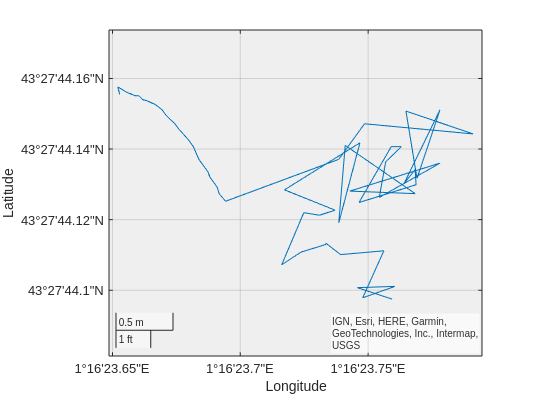

show(plotter,logimport)
msgs = readmsg(logimport, 'MessageName', 'GPS_RAW_INT', ...
                          'Time',[0 100]);
latlon = msgs.Messages{1};
% filter out zero-valued messages
latlon = latlon(latlon.lat ~= 0 & latlon.lon ~= 0, :);
figure()
geoplot(double(latlon.lat)/1e7, double(latlon.lon)/1e7);

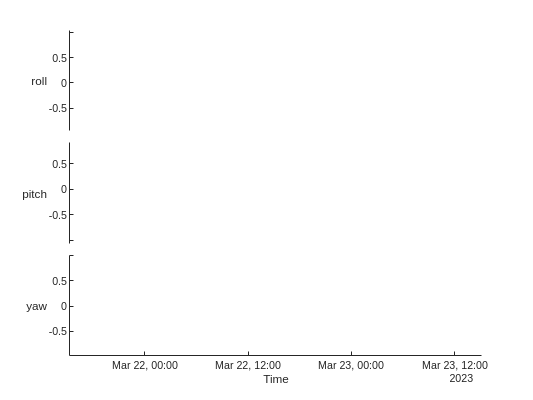


msgs = readmsg(logimport,'MessageName','ATTITUDE','Time',[0 100]);

figure()
stackedplot(msgs.Messages{1},{'roll','pitch','yaw'});